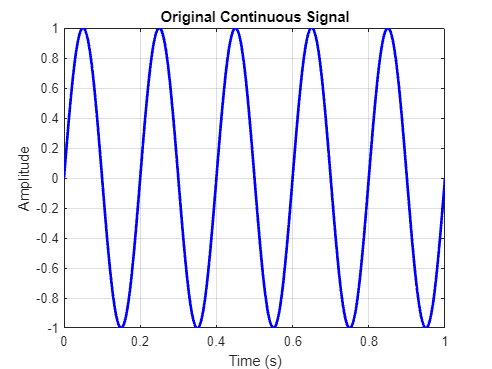

% Sampling and Reconstruction MATLAB Code

% Parameters
fs = 1000;
T = 1/fs;
t_continuous = 0:0.001:1;

% Original continuous signal
original_signal = sin(2*pi*5*t_continuous);

% Sampling
t_discrete = 0:T:1;
sampled_signal = sin(2*pi*5*t_discrete);

% Reconstruction using zero-order hold (nearest neighbor)
reconstructed_zoh = zeros(1, length(t_continuous));
for i = 1:length(t_discrete)
    index = find(t_continuous >= t_discrete(i), 1, 'first');
    reconstructed_zoh(index) = sampled_signal(i);
end

% Reconstruction using linear interpolation
reconstructed_linear = interp1(t_discrete, sampled_signal, t_continuous, 'linear');

% Plotting
figure;


plot(t_continuous, original_signal, 'b-', 'LineWidth', 2);
title('Original Continuous Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

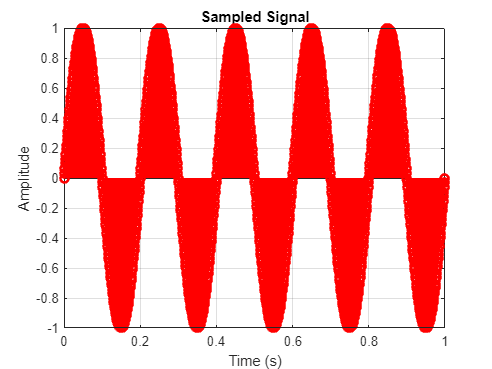


stem(t_discrete, sampled_signal, 'r', 'LineWidth', 2);
title('Sampled Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

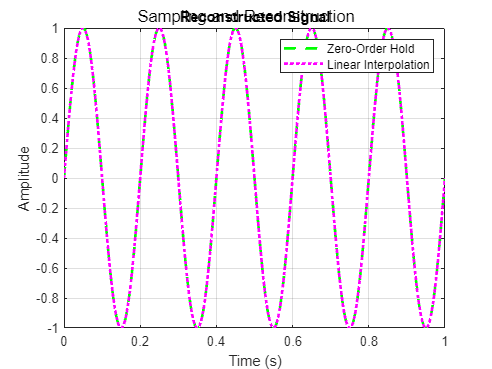


plot(t_continuous, reconstructed_zoh, 'g--', 'LineWidth', 2);
hold on;
plot(t_continuous, reconstructed_linear, 'm:', 'LineWidth', 2);
legend('Zero-Order Hold', 'Linear Interpolation');
title('Reconstructed Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Adjusting the plots
sgtitle('Sampling and Reconstruction');